# **Cálculo de **$\pi$

## **Primer método**


$$\frac{\pi }{4}=1-\frac{1}{3}+\frac{1}{5}-\frac{1}{7}+\frac{1}{9}+\ldotp \ldotp \ldotp \ldotp$$


Número fijo de iteraciones

n = 63663;
format long
suma = 1;
signo = -1;
pasado = 3;
for i=2:n
    suma = suma + signo * (1/pasado);
    signo = signo*(-1);
    pasado = pasado+2;
end    
piF = (4)*suma

piF =    3.141608361300682


Número variable de iteraciones

TOL =1e-5;% tolerancia
piAp = 0;
piA = 1; %sum es piA
i = 2;
signo = -1;
pasado = 3;
while relative_error(piA, piAp) > TOL
    piAp = piA;
    piA = piAp + signo * (1/pasado);
    signo = signo*(-1);
    pasado = pasado+2;
    i = i+1;
end
pifin = piA*4

pifin =    3.141608361300682


i

i =        63664


## **Método de Montecarlo**

n = 10000;
x = rand(1,n); %genero randoms en x y y
y = rand(1,n);
r2 = x.^2 + y.^2; %genero el vector r^2 para ver cuáles están dentro de los bounds

% indexamiento lógico (índices que cumplen mi condición)
inside = r2<= 1; %vector lógico de puntos que cumplen con la condicion
outside = r2>1; %vector logico de puntos que no cumplen con la condición (1 0 1 0 0....)

x(inside) %los que cumplieron en x, reindexados

ans =     0.8147    0.1270    0.6324    0.0975    0.2785    0.5469    0.9575    0.1576    0.9706    0.4854    0.8003    0.1419    0.4218    0.9157    0.7922    0.9595    0.0357    0.8491    0.6787    0.7577    0.7431    0.3922    0.6555    0.1712    0.7060    0.0318    0.2769    0.0462    0.0971    0.3171    0.0344    0.4387    0.3816    0.7655    0.7952    0.1869    0.4898    0.4456    0.6463    0.7094    0.7547    0.2760    0.6551    0.1626    0.1190    0.4984    0.9597    0.3404    0.2238    0.7513


y(inside) %los que cumplieron en y, reindexados

ans =     0.1538    0.8763    0.4071    0.1266    0.9254    0.0056    0.1864    0.0502    0.1445    0.4823    0.3381    0.2368    0.4509    0.1855    0.3243    0.2640    0.6964    0.3335    0.2878    0.2640    0.2599    0.6771    0.5198    0.0768    0.0558    0.2587    0.4399    0.2843    0.6788    0.6361    0.7468    0.5860    0.7731    0.3925    0.6053    0.2474    0.2902    0.0193    0.3473    0.1418    0.4115    0.1531    0.7392    0.0989    0.8206    0.2271    0.1069    0.6628    0.8146    0.6233


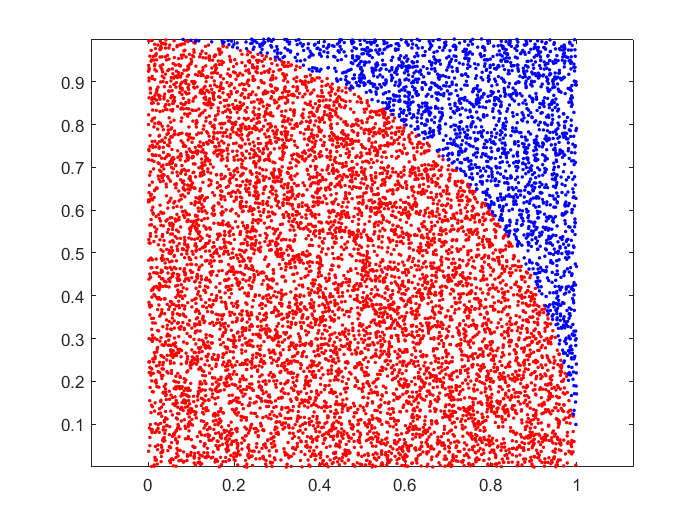



plot(x(inside),y(inside),'r.')
axis equal
hold on
plot(x(outside),y(outside),'b.')

size(inside)

ans =            1       10000


p = sum(inside)/n;

The logical indices contain a true value outside of the array bounds.

q = 1-p;
sd = sqrt(p*q);
alfa = 0.05;
z = norminv(1-alfa/2);
se = sd/sqrt(n);
fprintf('%7.4f +/- %6.4f\n',4*p,4*z*se)
